#  PMSG(Permanent Magnet Synchronous Generator)-Wind Power System

## 1. Introduction

A Type 4 wind power system, also known as a full-converter wind turbine system, is a modern wind energy generation system where the Permanent Magnet Synchronous Generator (PMSG) is fully decoupled from the grid using a back-to-back power converter. Unlike Type 1 and Type 2 systems, which rely on direct grid connection, and Type 3 systems, which use partial power conversion, Type 4 systems convert 100% of the generated power through power electronics. This configuration allows for wide-speed operation, full reactive power control, and enhanced grid compliance. The system consists of a wind turbine, a PMSG (or squirrel-cage induction generator), a rectifier-Inverter power converter and a control system. Type 4 wind turbines are commonly used in offshore and large-scale onshore wind farms, where grid stability, variable-speed operation, and high energy efficiency are critical.

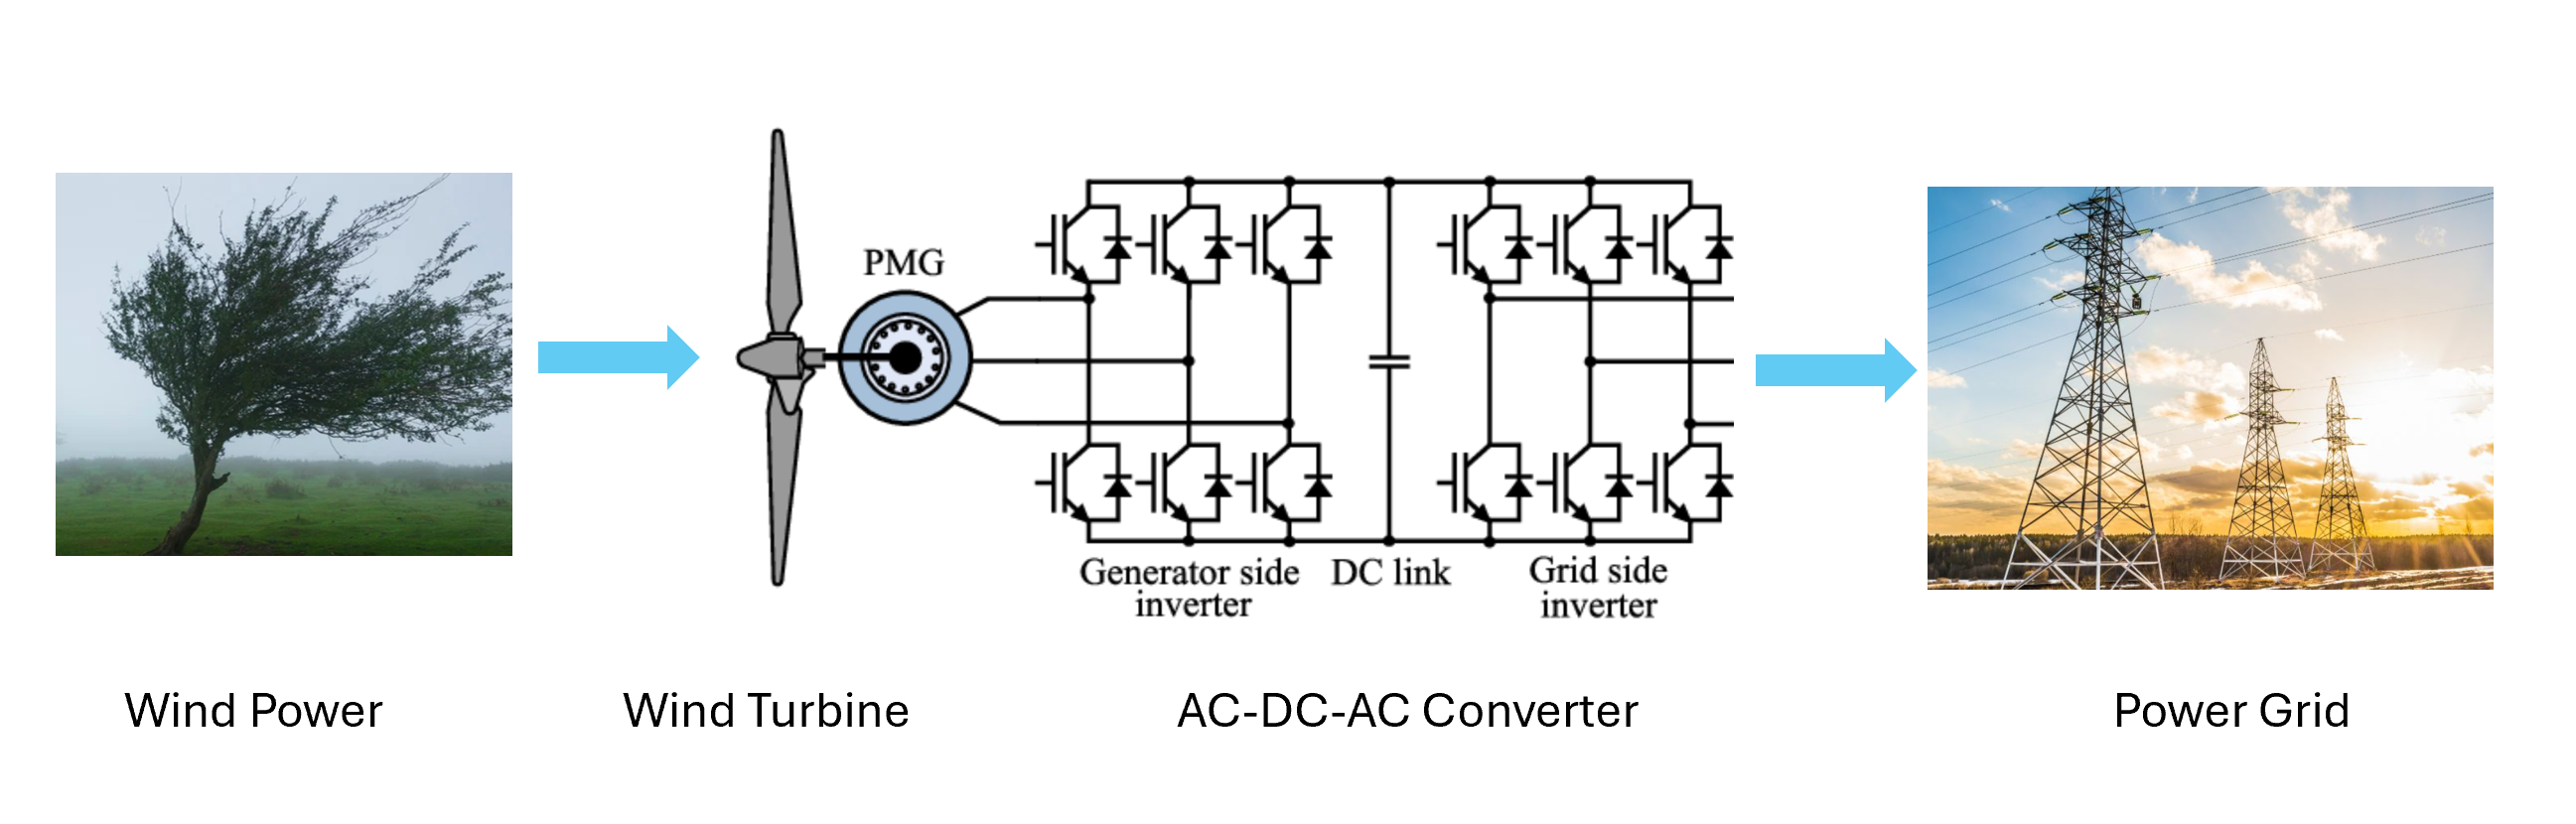

The structure of the PSMG-wind power system 

The following table details the main differences between the four types of wind power systems.

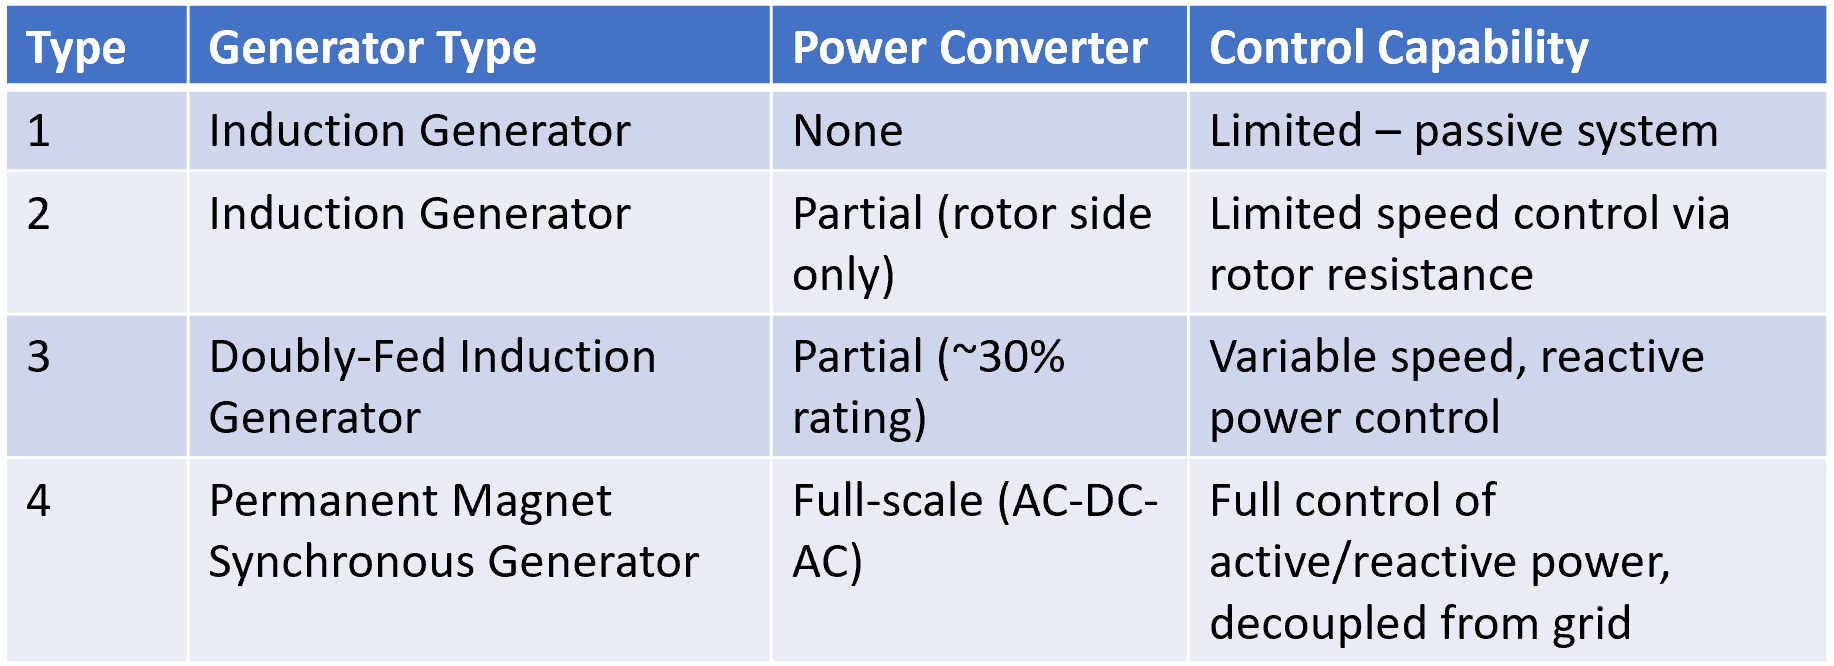

All four types of wind-power system

There are four key points in this module:

- Wind turbine simulation. 

- PMSG rotating speed control.

- DC-bus voltage control.

- Active and reactive power separate control.

## 2. Model Layout Overview

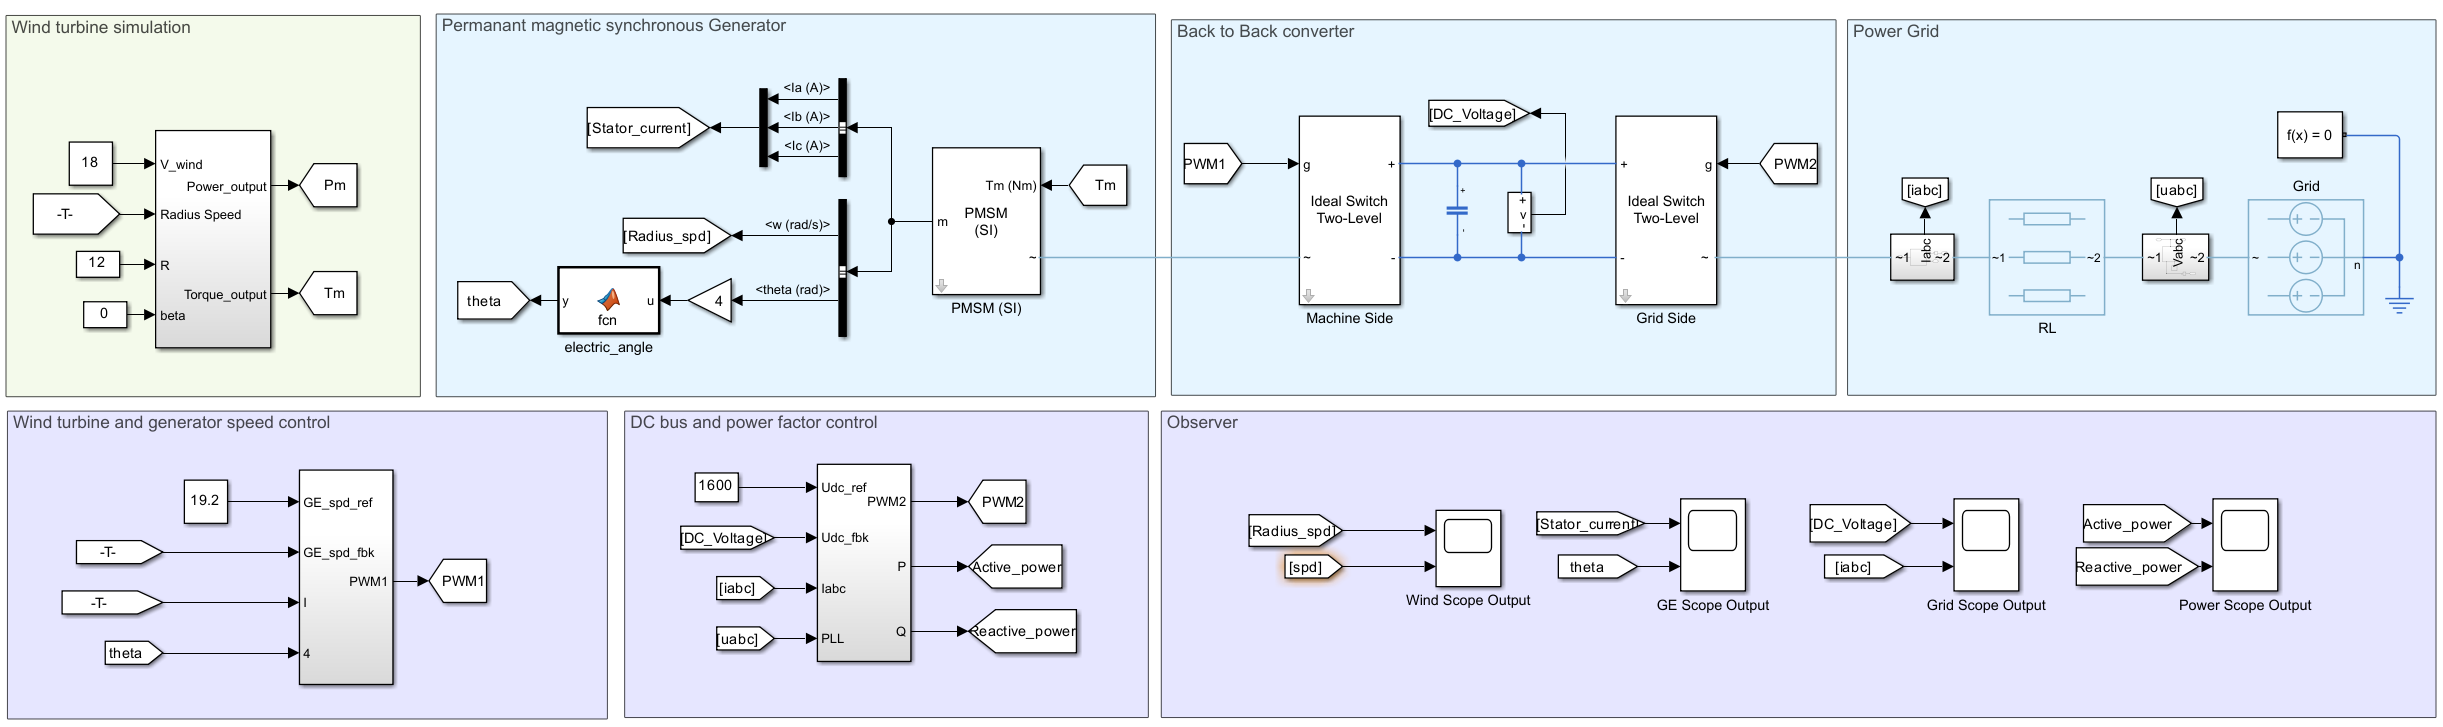

   PMSG-Wind Power

 
open_system("model/newnewPMSG.slx")

## 3. Simulation results overview

**Task 1.** Click the **Run** button and check the initial simulation results. **The simulation may take a few minutes.**

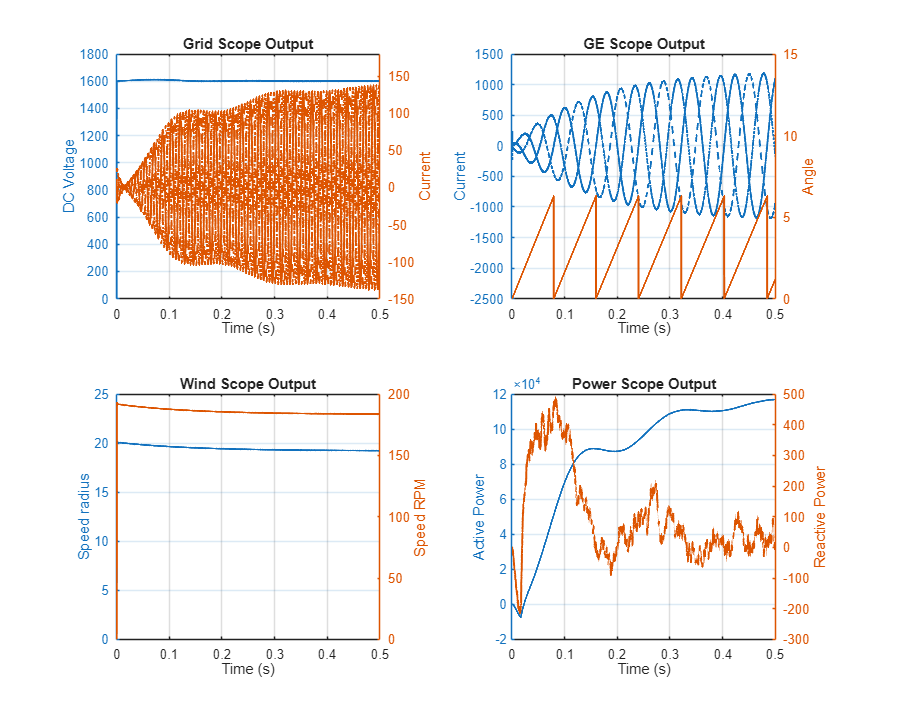

 
runmodel();

Now, let's dive deeper into the following four sections:

- Wind turbine model. 

- PMSG rotating speed control.

- DC-bus voltage control.

- Reactive Power Control.

### 3.1. Wind turbine model

The following block symbolizes the wind turbine. **Pm** and **Tm** here are the** power** output and **torque** output.

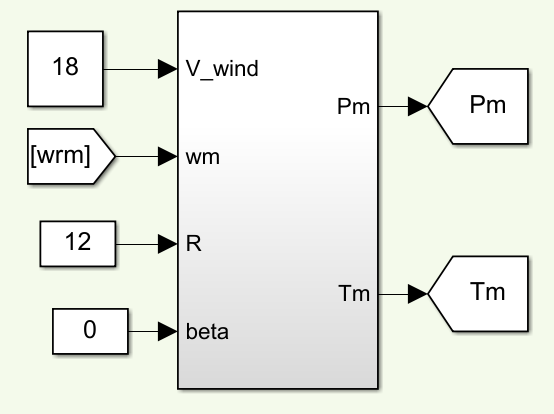

**Speed of wind (V_wind)**, **radius of the turbine (Wm)** and the **rotating speed (R) **will decide the **power** and **torque** output**.**

**Task 2. **Now, let's use a model of the wind turbine. Change input parameters and see how they impact the output.

Vwind=9.7

Vwind = 9.7000

Wm=13.5

Wm = 13.5000

Radius=4.6

Radius = 4.6000

 
open_system('model\turbine_simscape.slx');

'model\turbine_simscape.slx' is not a valid Simulink object name and there is no file with that name.

set_param('turbine_simscape/Constant', 'Value', num2str(Vwind));
set_param('turbine_simscape/Constant1', 'Value', num2str(Wm));
set_param('turbine_simscape/Constant5', 'Value', num2str(Radius));

warning('off','All')
simOut = sim('model\turbine_simscape.slx'); 
out=simOut;

turbine_data = out.turbine;
time = turbine_data.time; 


signal1 = turbine_data.signals(1).values; 
signal2 = turbine_data.signals(2).values; 

figure('Position', [100, 100, 1000, 800]); 

yyaxis left
plot(time, signal1, 'b', 'LineWidth', 1.5); 
hold on;
yyaxis right
plot(time, signal2, 'r', 'LineWidth', 1.5);
hold off;
title('turbine Scope Output');
xlabel('Time (s)');
ylabel('Signal Value');
legend('Power', 'Torque');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('Power')
yyaxis(ax,'right')
ylabel('Torque')

### 3.2. PMSG speed Control

In this section, you will need to make changes directly in the model itself. Click the button below to open the model and familiarize with it.

 
open_system('model\newnewPMSG.slx');

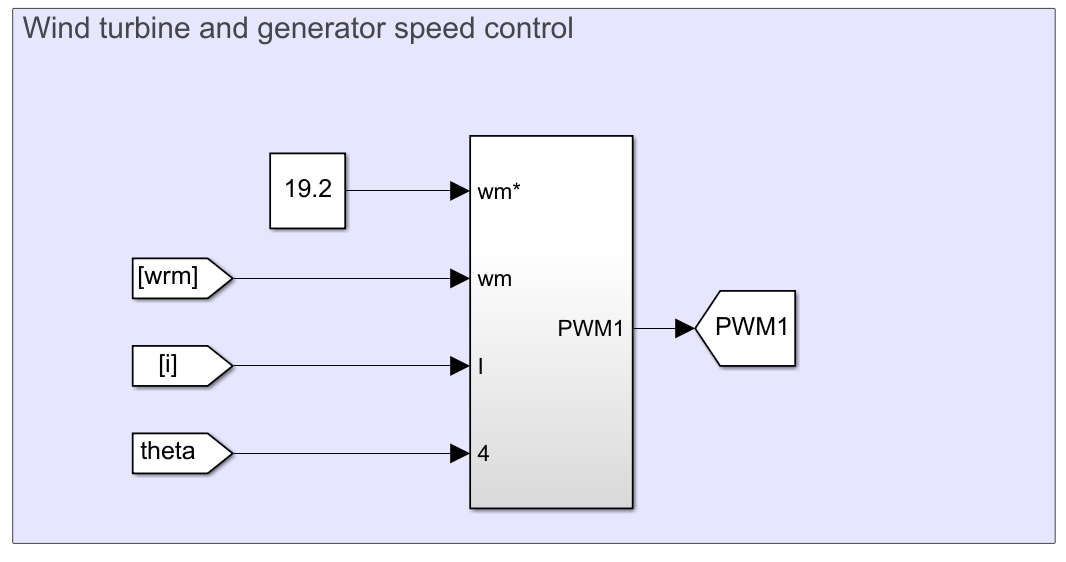

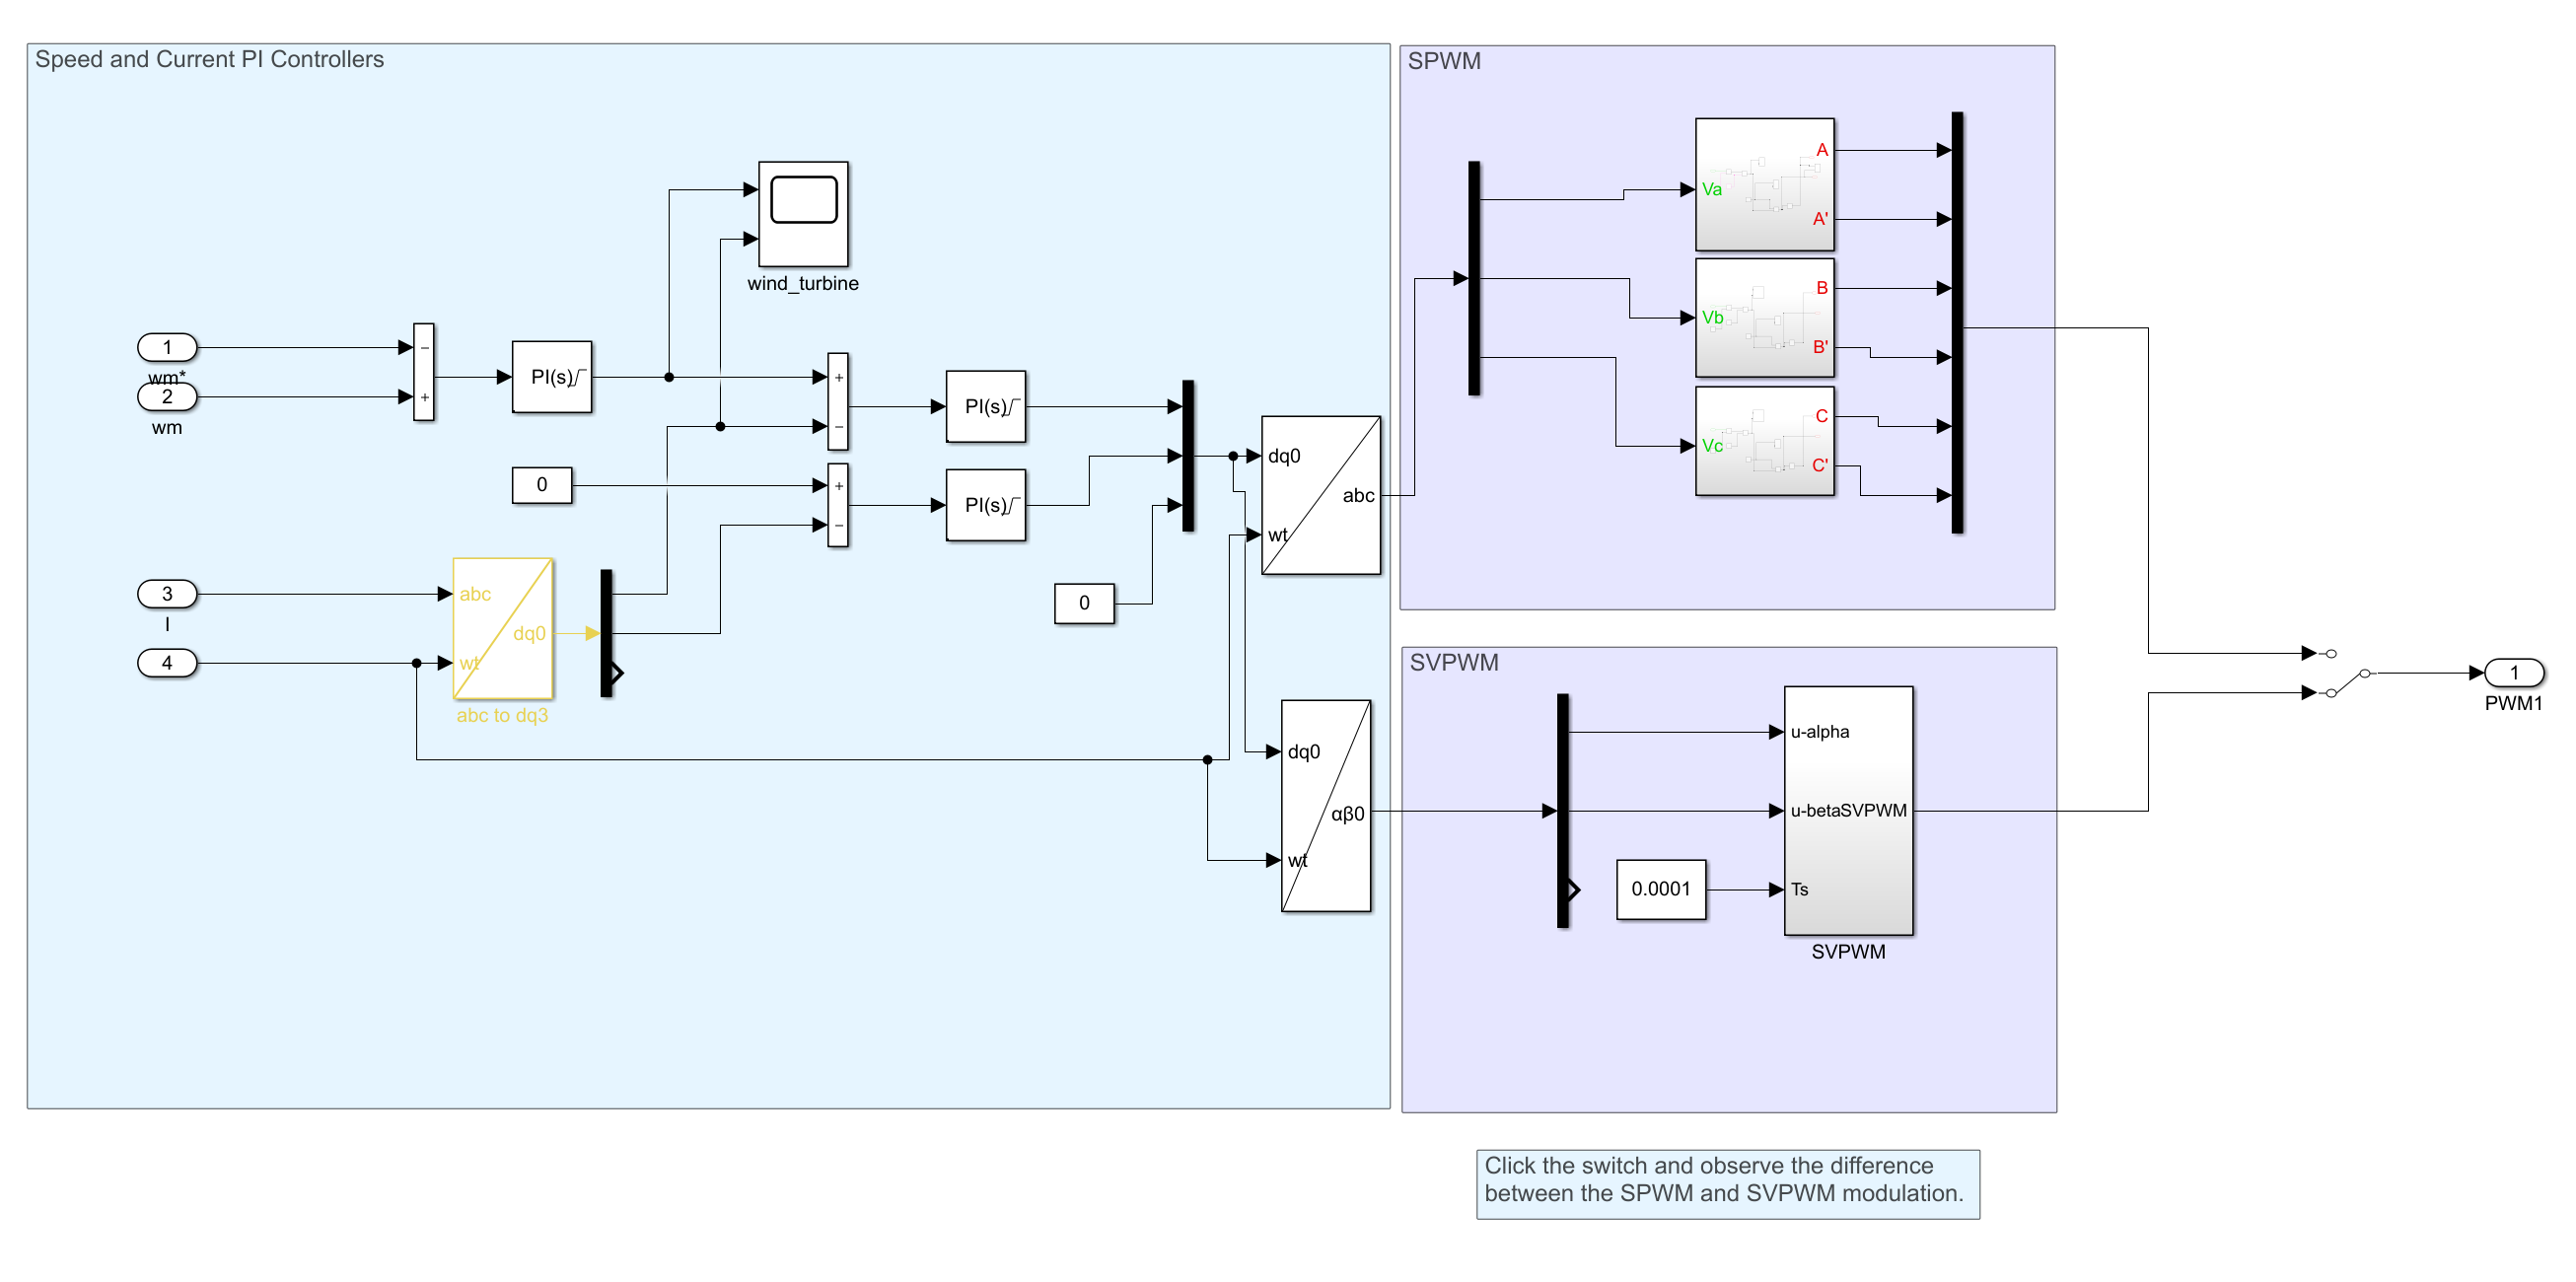

The Structure of the PMSG Speed controllers 

**Task 3. **Use the slider below to change the target generator radius speed **(GE_spd_ref) **and see how the output changes.

GE_spd_ref=18.8
open_system('model\newnewPMSG.slx');
set_param('newnewPMSG/Constant1', 'Value', num2str(GE_spd_ref));
 
runmodel();

Also, try the two different modulation methods in the model by clicking the switch block. See which performance is better.

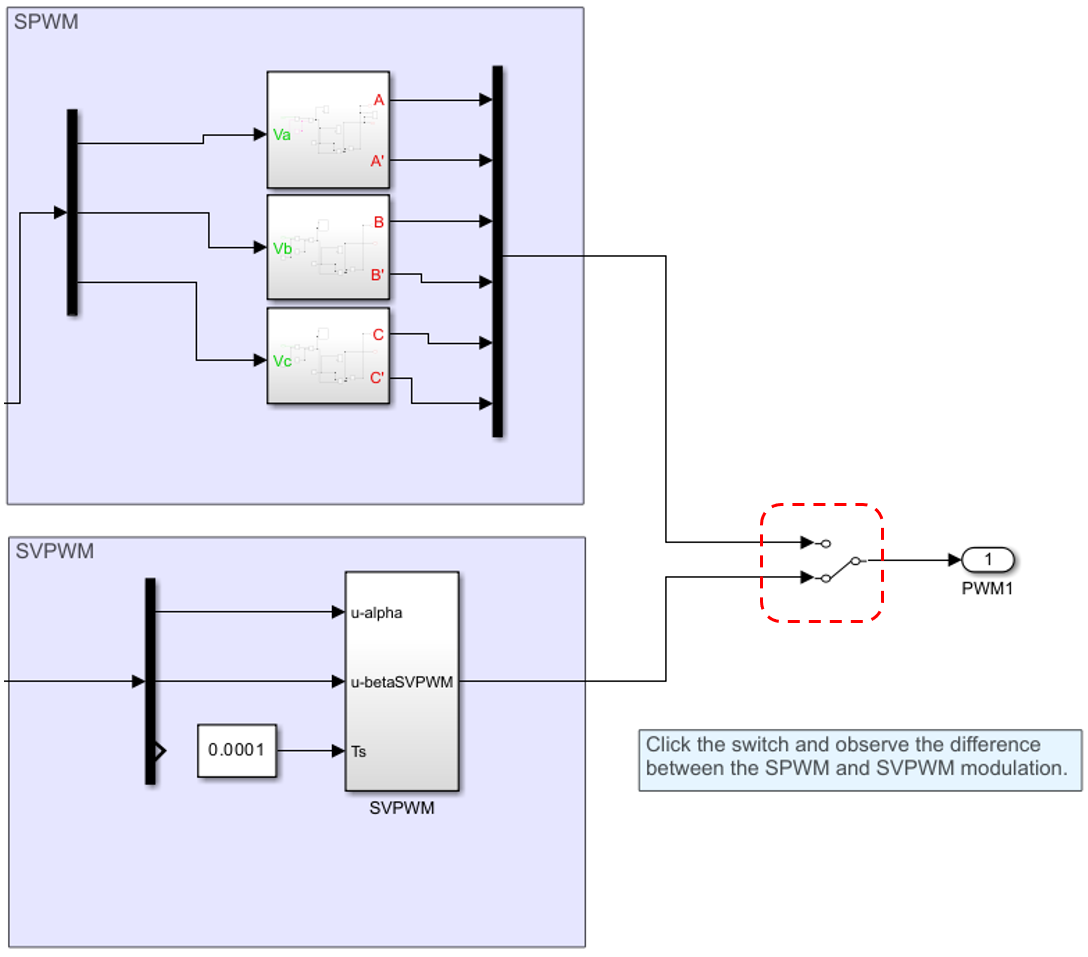

**Question:** When changing wm to a value below 19, what will happen? And in order to solve the question, what should it be changed in the model?

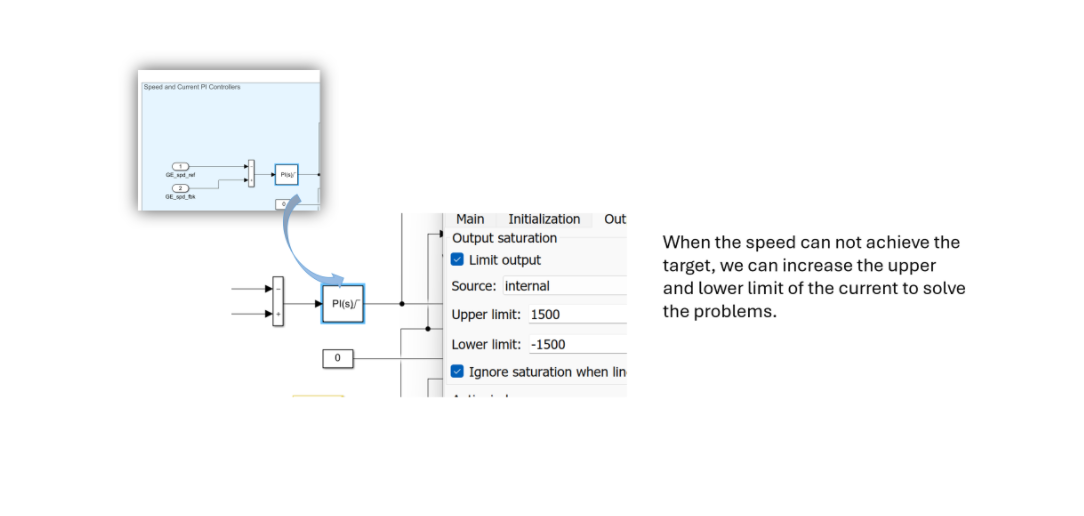

showpic1(true);

### 3.3. DC bus Control and Power factor Control

The DC-bus in a wind power conversion system (especially in a Type 4 topology) acts as the energy buffer between the generator-side converter and the grid-side converter. It holds the intermediate DC voltage that links the AC-DC and DC-AC conversion stages.

Why do we control the DC-bus voltage?

- To ensure stable power transfer between the generator and the grid.

- To protect the converter components from overvoltage or undervoltage.

- To maintain sufficient voltage headroom for proper PWM operation of the Inverter.

Why is the DC-bus voltage adjustable?

- It can be tuned depending on system requirements such as power level, grid voltage, and control bandwidth.

- In some systems, a higher DC-bus voltage may improve efficiency and reduce current stress on switching devices.

- During startup or fault conditions, adjusting the reference DC-bus voltage helps maintain system stability and enables safe operation.

- Designers may also adjust it based on the capacitor size, energy storage capability, or desired dynamic response.

In the Simulink model, changing the reference value of the DC-bus allows users to observe how the system responds dynamically and whether the DC-bus control loop is fast and robust enough to regulate the voltage under varying load or generation conditions.

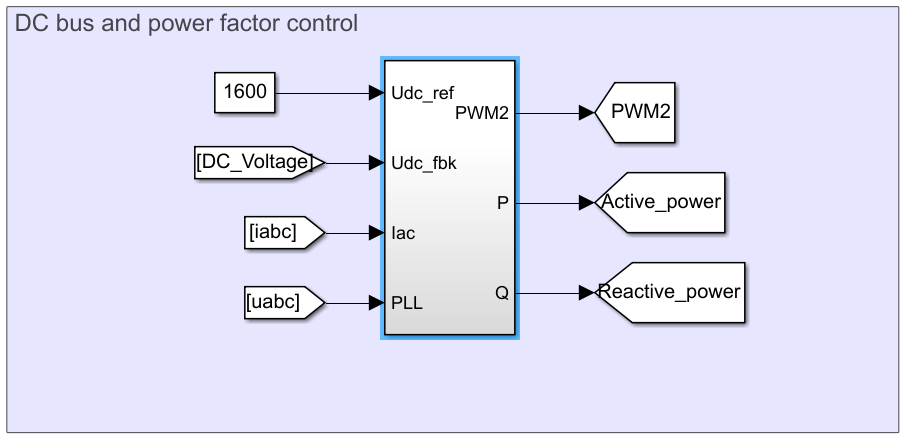

Change the Udc reference and the initial voltage value of the target capacitor as follows:

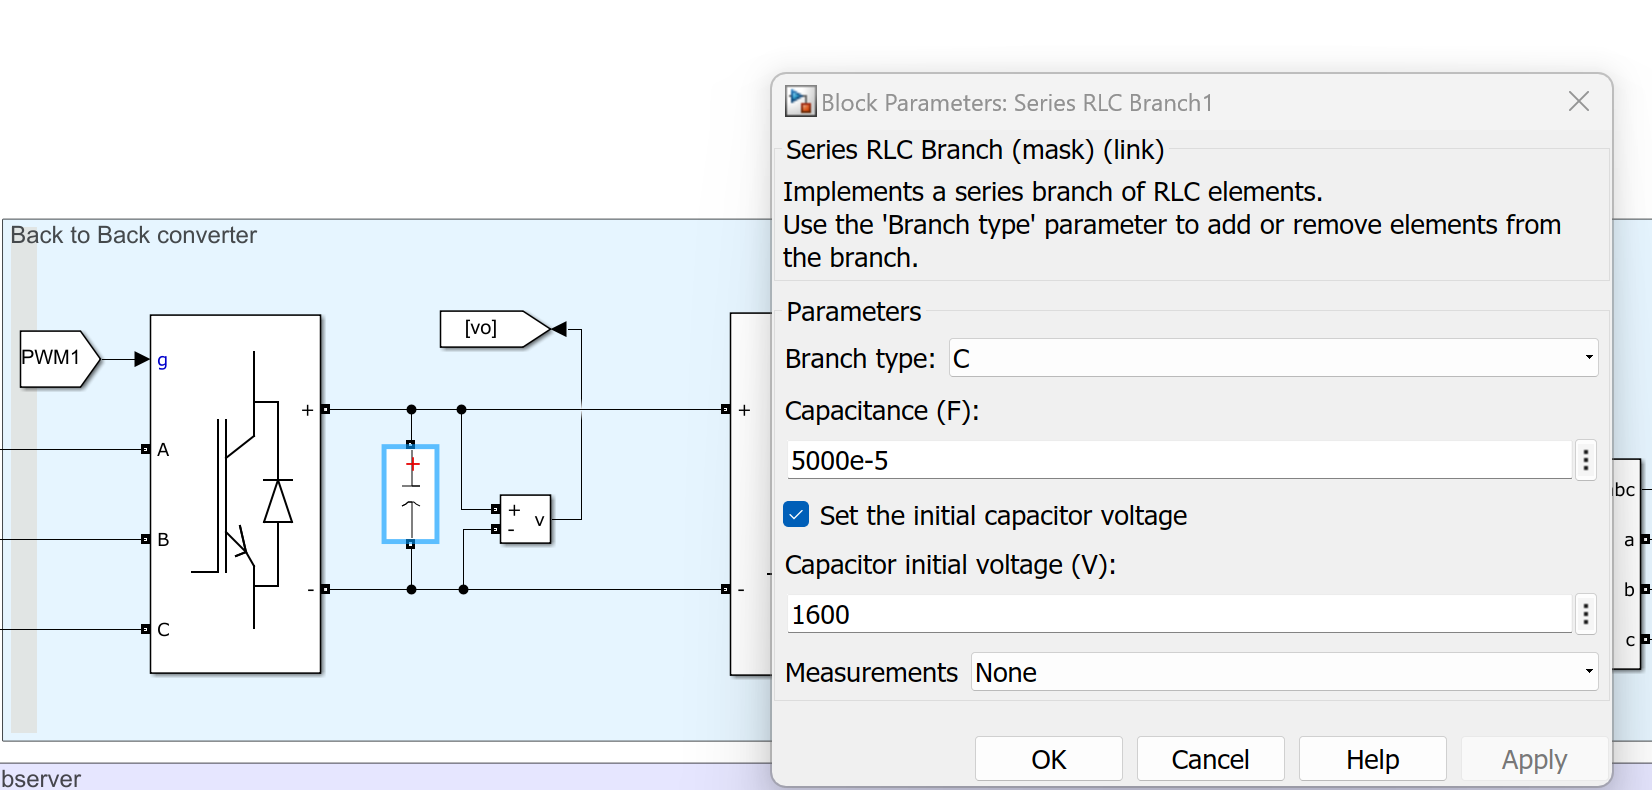

### 3.4. Reactive Power Control (Power factor control)

In order to control the active and reactive power (power factor) to 1 (highest efficiency), The Q-axis current (Iq) is always set to zero, as shown below:

Try and see what will happen

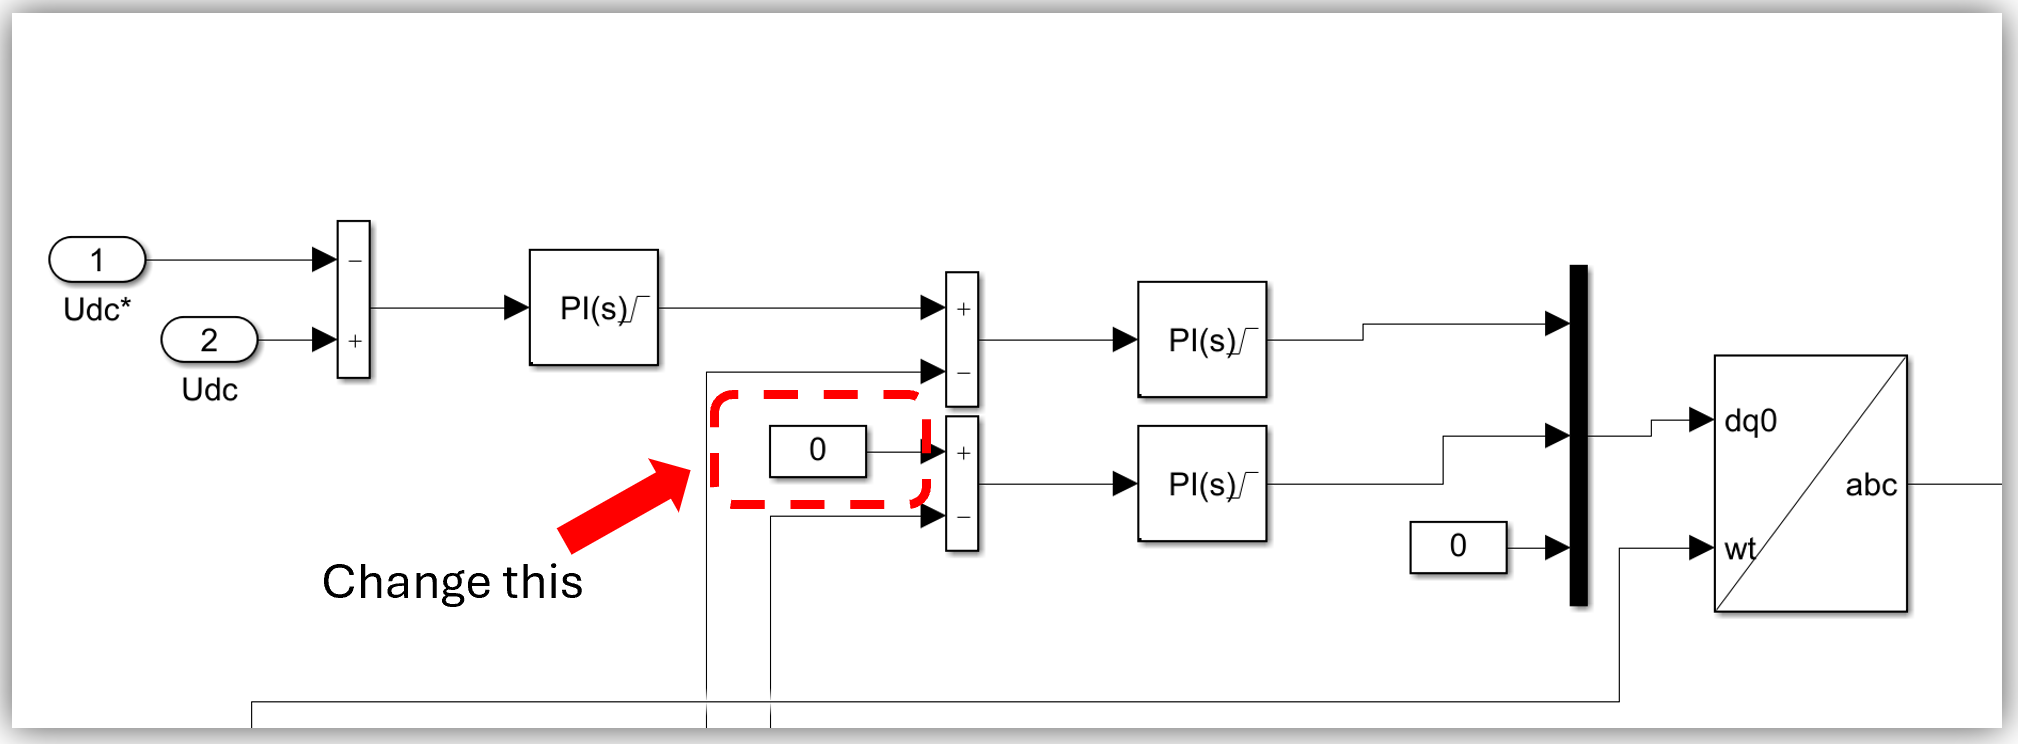

In reactive power control, setting the q-axis current to zero (with the d-axis aligned to the grid voltage) eliminates reactive power exchange between the converter and the grid, ensuring that all delivered power is purely active, the power factor is unity, and system efficiency and voltage stability are maintained.

**Question:** If the q-axis current reference is varied instead of fixed at zero, how can the converter be controlled to provide both active and reactive power simultaneously, and what would be the impact on power factor and system efficiency?

## 4. Example Simulation Results

This section is intended to show what the standard response of important variables in the system should be. 

result("Constant Circuit")

## 5. Conclusion

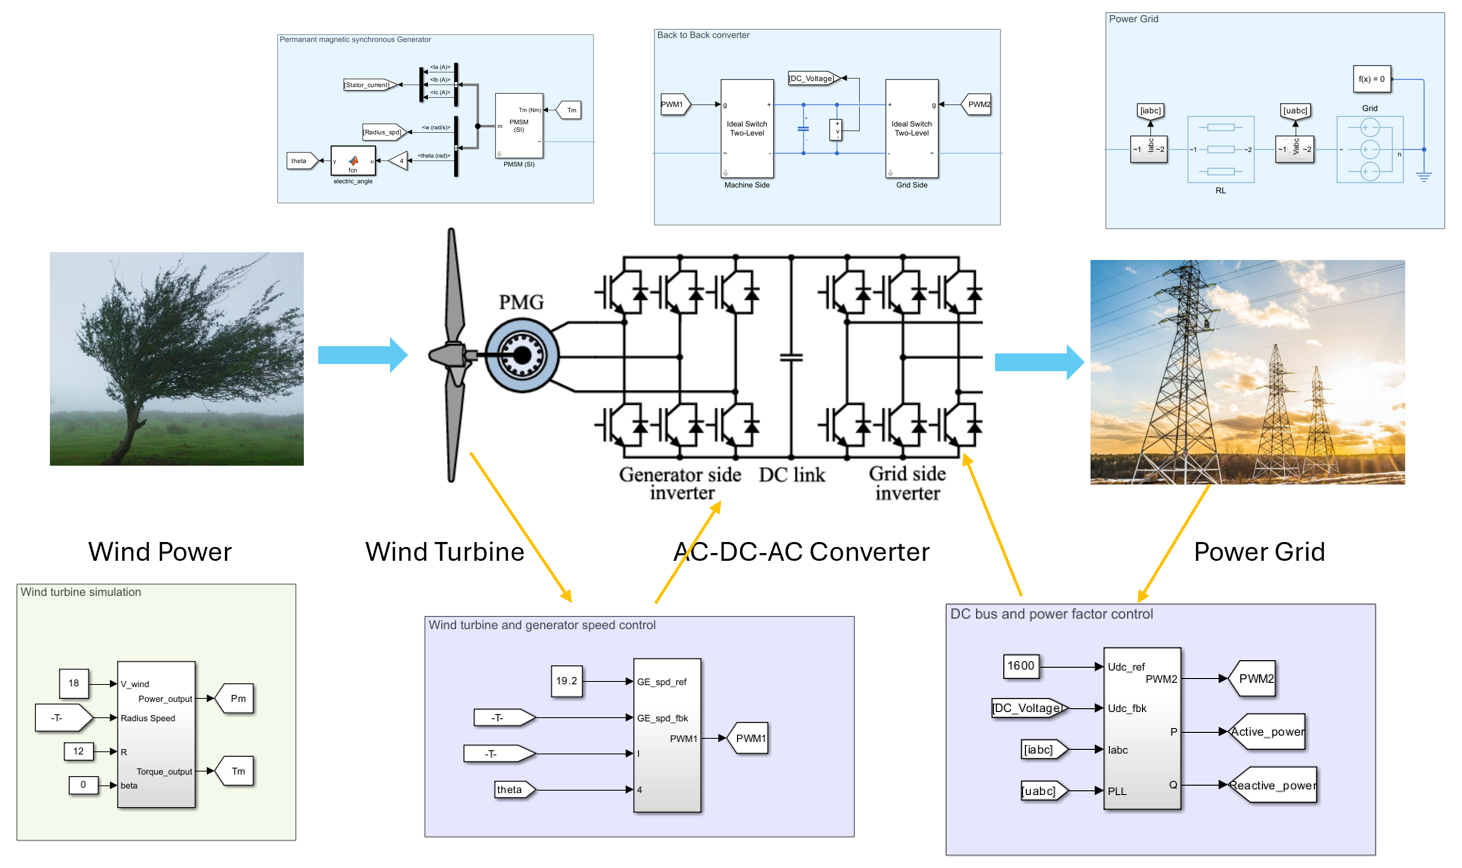

The above figure illustrates how each control block in the Simulink model symbolizes each part of the PMSG-Wind Power System. By embedding these control algorithms into microcontrollers and deploying them in real-world systems, engineers can achieve efficient and reliable wind energy conversion. This simulation-to-hardware workflow enables rapid prototyping, real-time testing, and seamless implementation of advanced control strategies for power regulation, generator speed management, and grid integration. Ultimately, it bridges the gap between theoretical design and practical application in renewable energy systems.

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "LLC Converter" "Hbridge"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "LLC Converter"
        rect = imread("Images/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
    elseif opt == "Hbridge"
        rect = imread("Images/Hbridge.png");
        imshow(rect, 'Interpolation', 'bilinear');
    end
end
end


function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Constant Circuit" "Constant Voltage" "PowerGrid" "PowerFlow"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Constant Circuit"
        rect = imread("Images/Result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Constant Voltage"
        rect = imread("Images/Result2.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "PowerGrid"
        rect = imread("Images/Result3.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "PowerFlow"
        rect = imread("Images/Result4.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end





function exerciseSol1(A,B)
    % Provides solution for Exercise 1
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        disp("Please select one that apply!")
    elseif A
        disp("Correct!")
    else 
        warning("Incorrect. please review the Circuit part.")
    end
end

function exerciseSol2(A,B,C)
    % Provides solution for Exercise 2
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        disp("Please select one that apply!")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. Plz check the control part again")
    end
end
function exerciseSol3(A,B,C)
    % Provides solution for Exercise 3
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        disp("Please select one that apply!")
    elseif C
        disp("Correct!")
    else 
        warning("Incorrect.")
    end
end

function showpic1(A)
    % Provides solution for Exercise 1
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/CC.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end
function showpic2(A)
    % Provides solution for Exercise 1
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end

function runmodel()
warning('off', 'all'); 
simOut = sim('model\newnewPMSG.slx'); 
out=simOut;


ge_data = out.get('GE');
power_data = out.get('power');
wind_data = out.get('wind');
grid_data = out.get('Grid');


time = grid_data.time; 


signal1 = squeeze(grid_data.signals(1).values); 
signal2 = squeeze(grid_data.signals(2).values); 


signal3 = squeeze(ge_data.signals(1).values); 
signal4 = squeeze(ge_data.signals(2).values);


signal5 = squeeze(wind_data.signals(1).values); 
signal6 = squeeze(wind_data.signals(2).values);


signal7 = squeeze(power_data.signals(1).values); 
signal8 = squeeze(power_data.signals(2).values);


figure('Position', [100, 100, 1000, 800]); 


subplot(2,2,1); 
yyaxis left
plot(time, signal1, 'LineWidth', 1.5); 
hold on;
yyaxis right
plot(time, signal2, 'LineWidth', 1.5);
hold off;
ylim([-150 180]) 
title('Grid Scope Output');
xlabel('Time (s)');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('DC Voltage')
yyaxis(ax,'right')
ylabel('Current')

subplot(2,2,2); 
yyaxis left
plot(time, signal3, 'LineWidth', 1.5);
hold on;
ylim([-2500 1500]) 
yyaxis right
plot(time, signal4, 'LineWidth', 1.5);
hold off;
ylim([0 15]) 
title('GE Scope Output');
xlabel('Time (s)');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('Current')
yyaxis(ax,'right')
ylabel('Angle')


subplot(2,2,3); 
yyaxis left
plot(time, signal5, 'LineWidth', 1.5);
hold on;
yyaxis right
plot(time, signal6, 'LineWidth', 1.5);
hold off;
title('Wind Scope Output');
xlabel('Time (s)');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('Radius Speed')
yyaxis(ax,'right')
ylabel('Speed RPM')


subplot(2,2,4); 
yyaxis left
plot(time, signal7, 'LineWidth', 1.5);
hold on;
yyaxis right
plot(time, signal8, 'LineWidth', 1.5);
hold off;
title('Power Scope Output');
xlabel('Time (s)');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('Active Power')
yyaxis(ax,'right')
ylabel('Reactive Power')


end
